% Motor params
R = 5.5;                % [Ohm]
L = 0.0028;             % [H]
phi = 0.5;              % [Wb]
k = 1;                  % []
J = 0.5;                % [kg m^2]
Cr = 0.1;               % [Nm] Assumed Cr constant.
V = 24;

% Building the system
H = [L 0; 0 J];
A = inv(H)*[-R -k*phi; k*phi 0];
B = inv(H)*[V ; -Cr];
C = [0 1];

% Steady state solution with a unit voltage step input
-inv(A)*B % current / angular speed

ans =     0.2000
   45.8000


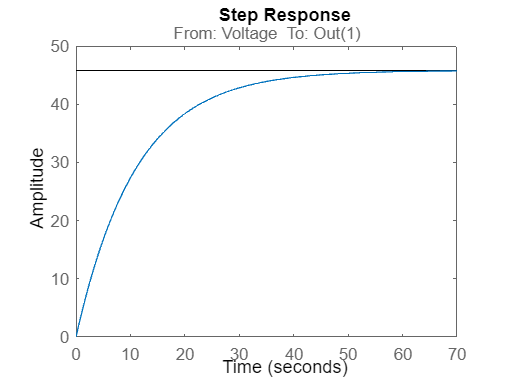

% OUTPUT
%
%ans =
%
%    0.2000
%   45.8000

% State space system
sys = ss(A, B, C, 0, 'StateName',{'Current' 'Angular speed'},'InputName','Voltage');

% System response to unit voltage step
step(sys)

Series connection with PI regulator and then negative feedback

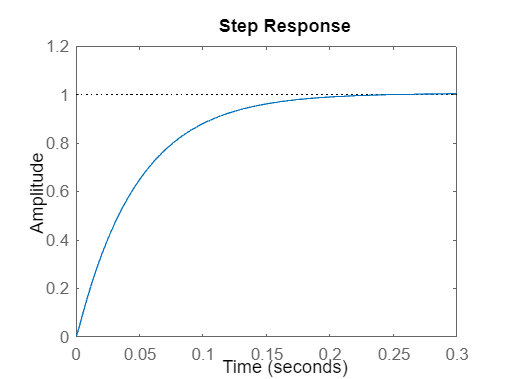

t = feedback(series(pid(5,1), sys), 1);
% New system response to a unit voltage step
step(t)